opts = delimitedTextImportOptions("NumVariables", 25);
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["FilePath", "ID", "AuthorsNote", "StrideSpeed", "StrideLengthFR", "StepLengthFR", "StepWidthFR", "StrideLengthFL", "StepLengthFL", "StepWidthFL", "StrideLengthBR", "StepLengthBR", "StepWidthBR", "StrideLengthBL", "StepLengthBL", "StepWidthBL", "TemporalSymmetryF", "TemporalSymmetryB", "DutyFactorF", "DutyFactorB", "AngularVelocity", "NoseLateralDisplacementBR", "NoseLateralDisplacementPhaseOffsetBR", "TailLateralDisplacementBR", "TailLateralDisplacementPhaseOffsetBR"];
opts.VariableTypes = ["string", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts = setvaropts(opts, "FilePath", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["FilePath", "AuthorsNote"], "EmptyFieldRule", "auto");

data = readtable("Normalized Gait Analysis Full.csv", opts);

clear opts

opts = spreadsheetImportOptions("NumVariables", 6);
opts.Sheet = "Genotype";
opts.DataRange = "A2:F24";
opts.VariableNames = ["Tag", "Sex", "Genotype", "DOB", "Month", "Injections"];
opts.VariableTypes = ["double", "categorical", "categorical", "datetime", "datetime", "datetime"];
opts = setvaropts(opts, ["Sex", "Genotype"], "EmptyFieldRule", "auto");

genotype = readtable("NP recodring file list.xlsx", opts, "UseExcel", false);

clear opts

genotype(:, 3)

ans = 23×1 table
    Genotype
    ________

       KO   
       WT   
       WT   
       KO   
       KO   
       WT   
       WT   
       KO   
       WT   
       WT   
       KO   
       KO   
       KO   
       WT   
       WT   
       KO   


data = innerjoin(data, genotype, "LeftKeys", "ID", "RightKeys", "Tag")

data = 96×30 table
                                                      FilePath                                                       ID      AuthorsNote      StrideSpeed    StrideLengthFR    StepLengthFR    StepWidthFR    StrideLengthFL    StepLengthFL    StepWidthFL    StrideLengthBR    StepLengthBR    StepWidthBR    StrideLengthBL    StepLengthBL    StepWidthBL    TemporalSymmetryF    TemporalSymmetryB    DutyFactorF    DutyFactorB    AngularVelocity    NoseLateralDisplacementBR    NoseLateralDisplacementPhaseOffsetBR    TailLateralDisplacementBR    TailLateralDisplacement

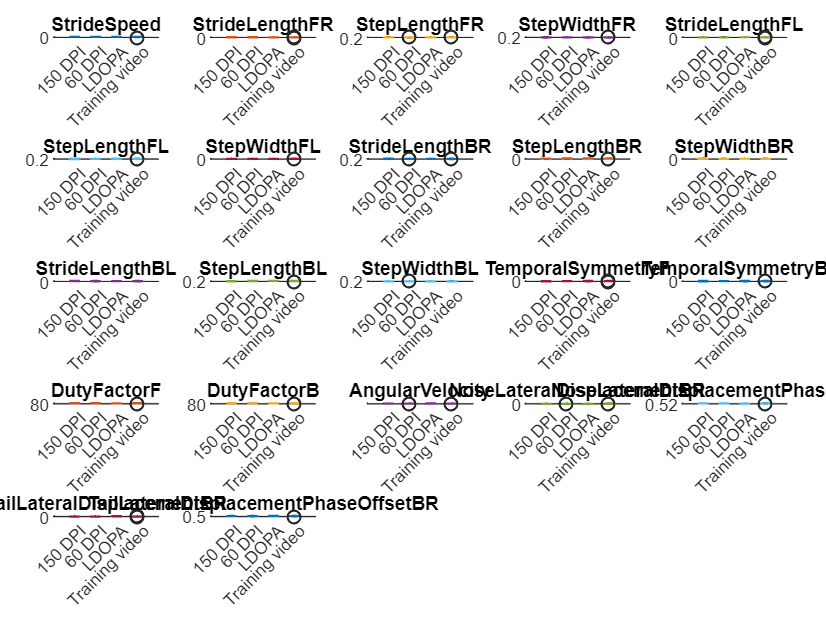

group = categorical(data.AuthorsNote(data.Genotype == "KO"));
vars = data.Properties.VariableNames(4:25);

metricColors = lines(numel(vars));

figure
tiledlayout("flow", "TileSpacing", "compact", "Padding", "compact")

for i = 1:numel(vars)
    nexttile

    b = boxchart(group, data{data.Genotype == "KO", vars{i}});
    b.BoxFaceColor = metricColors(i,:);
    b.MarkerColor = [0.15 0.15 0.15];
    b.WhiskerLineColor = [0.25 0.25 0.25];

    title(vars{i}, "Interpreter", "none")
    xtickangle(45)
    grid on
end